# Nonlinear system identification of the two-tank problem

This script was written for and used in the MATLAB Tech Talk video called "Nonlinear System Identification | System Identification, Part 3" which can be found on mathworks.com and youtube.com.

clear; close all;

load tankdata.mat

## Review data

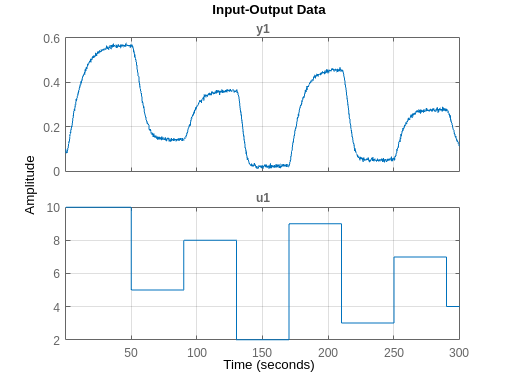

% Estimation data
a = figure;
b = plot(data_est);
% set(findall(gca, 'Type', 'Line'),'LineWidth',2);
grid on

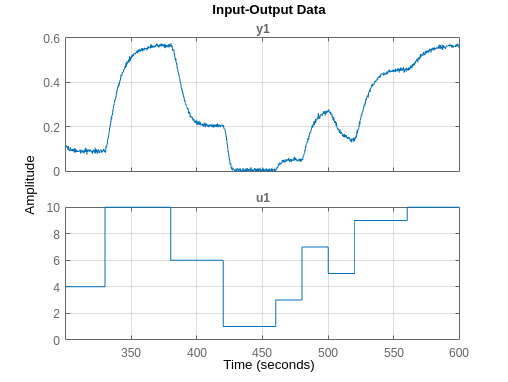

% Validation data
figure
plot(data_val);
% set(findall(gca, 'Type', 'Line'),'LineWidth',2);
grid on

## NLARX Model (Linear regressors + Linear output function + Offset)

## Model Structure

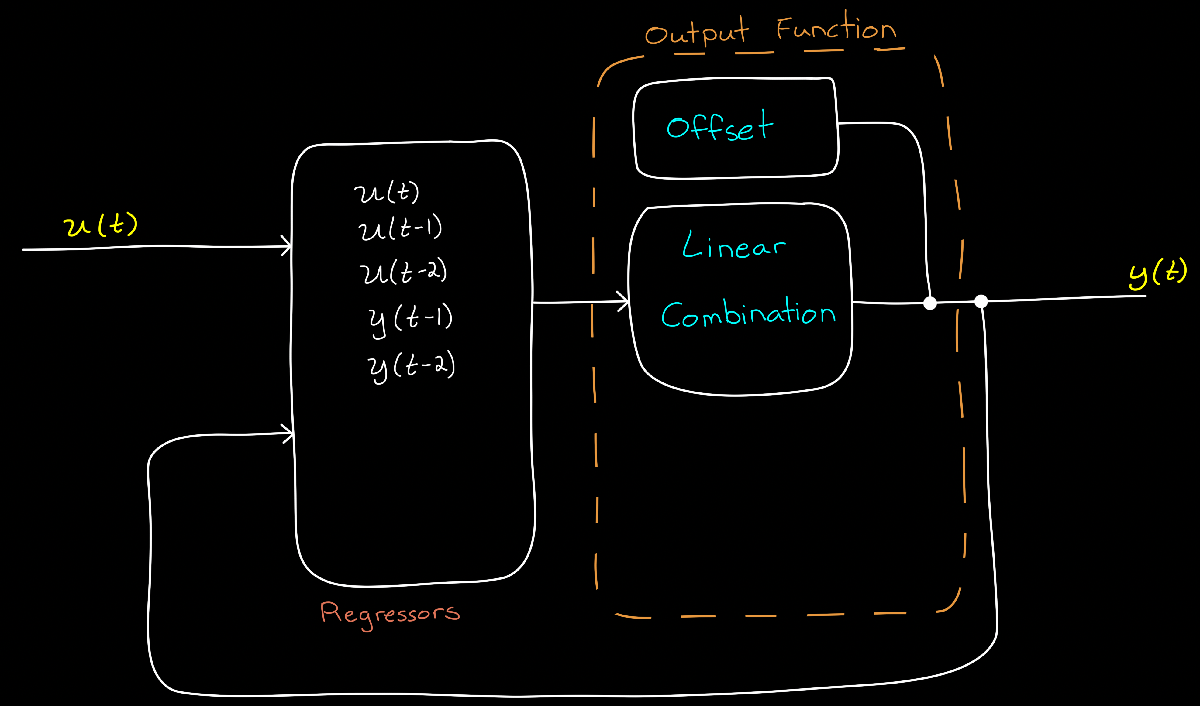

names = [data_est.OutputName, data_est.InputName];

% Define linear regressor vector
% L = [ y1(t-1);
%       y1(t-2);
%       u1(t);
%       u1(t-1);
%       u1(t-2) ]

L = linearRegressor(names,{1:2,0:2});

## Fit the model to the data

NL1 = nlarx(data_est, L, idLinear);

## Model Validation

Review the model

NL1.OutputFcn

ans = Linear Function
Inputs: y1(t-1), y1(t-2), u1(t), u1(t-1), u1(t-2)
Output: y1(t)

 Nonlinear Function: Linear with offset
 Linear Function: initialized to [0.129 0.0203 -0.00911 -0.107 0.000451]
 Output Offset: initialized to -4.18e-17

       Inputs: {'y1(t-1)'  'y1(t-2)'  'u1(t)'  'u1(t-1)'  'u1(t-2)'}
      Outputs: {'y1(t)'}
    LinearFcn: 'Linear function parameters'
       Offset: '

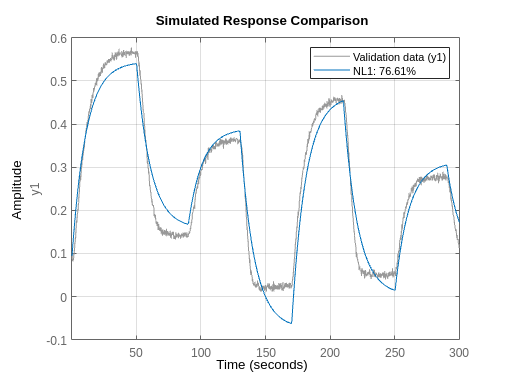

compare(data_est, NL1)
% set(findall(gca, 'Type', 'Line'),'LineWidth',4);
grid on

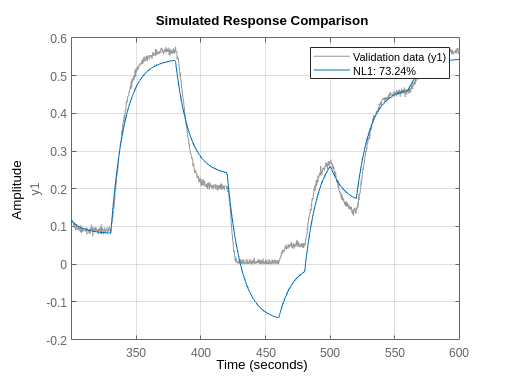

compare(data_val, NL1)
% set(findall(gca, 'Type', 'Line'),'LineWidth',4);
grid on

## NLARX Model (Nonlinear regressors + Linear output function + Offset)

## 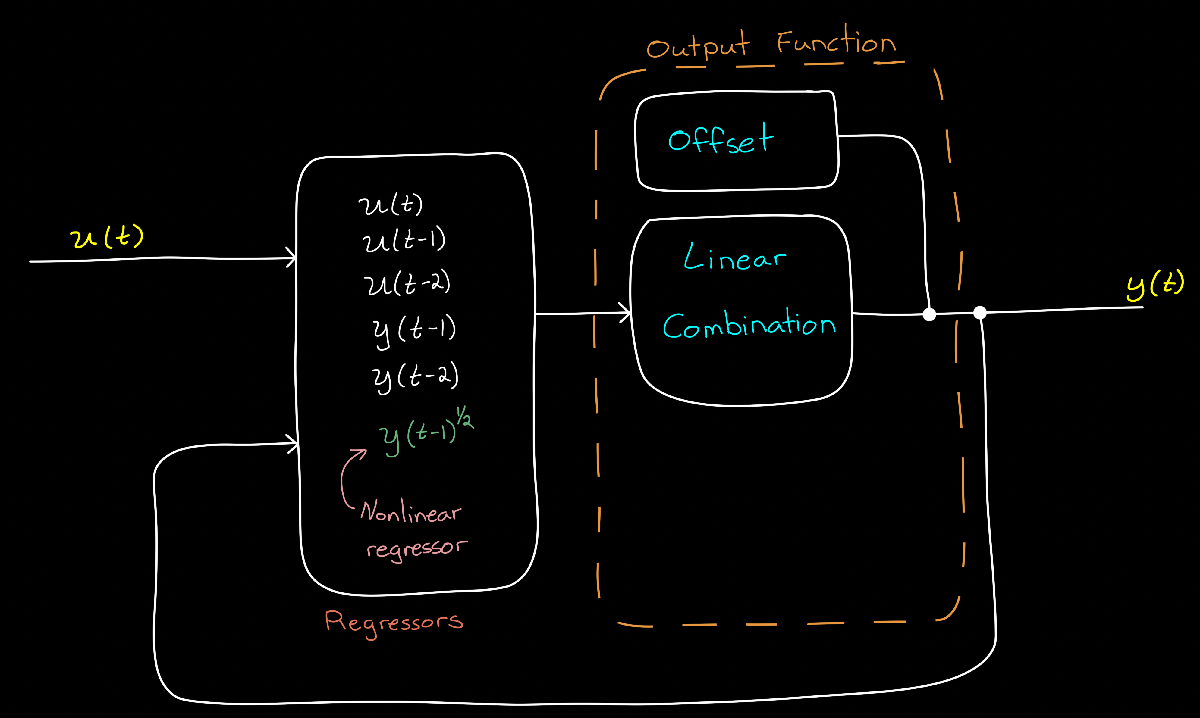

## Define the custom regressor for $\sqrt{y_1 \left(t-1\right)}$

C = customRegressor({'y1'},{1}, @(y)sqrt(y));
R = [L;C];

## Fit the model to the data

NL3 = nlarx(data_est, R, idLinear);

## Model Validation

Review the model

NL3.OutputFcn

ans = Linear Function
Inputs: y1(t-1), y1(t-2), u1(t), u1(t-1), u1(t-2), sqrt(y1(t-1))
Output: y1(t)

 Nonlinear Function: Linear with offset
 Linear Function: initialized to [0.129 0.0235 -0.0399 -0.0982 0.0125 -0.0005]
 Output Offset: initialized to -3.61e-17

       Inputs: {'y1(t-1)'  'y1(t-2)'  'u1(t)'  'u1(t-1)'  'u1(t-2)'  'sqrt(y1(t-1))'}
      Outputs: {'y1(t)'}
    LinearFcn: 'Linear function parameters'
       Offset: '

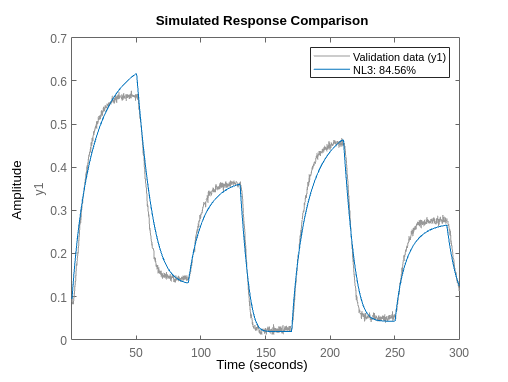

compare(data_est, NL3)

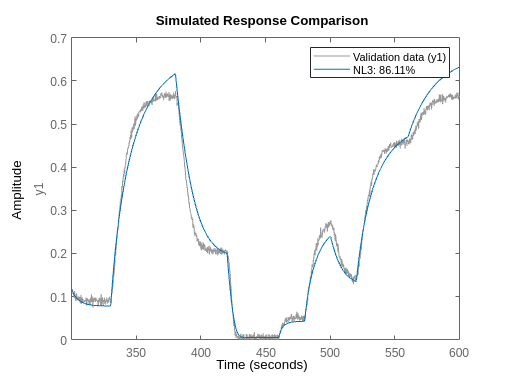

compare(data_val, NL3)

## NLARX Model (Nonlinear regressors + Linear/Nonlinear output function + Offset)

## Model Structure

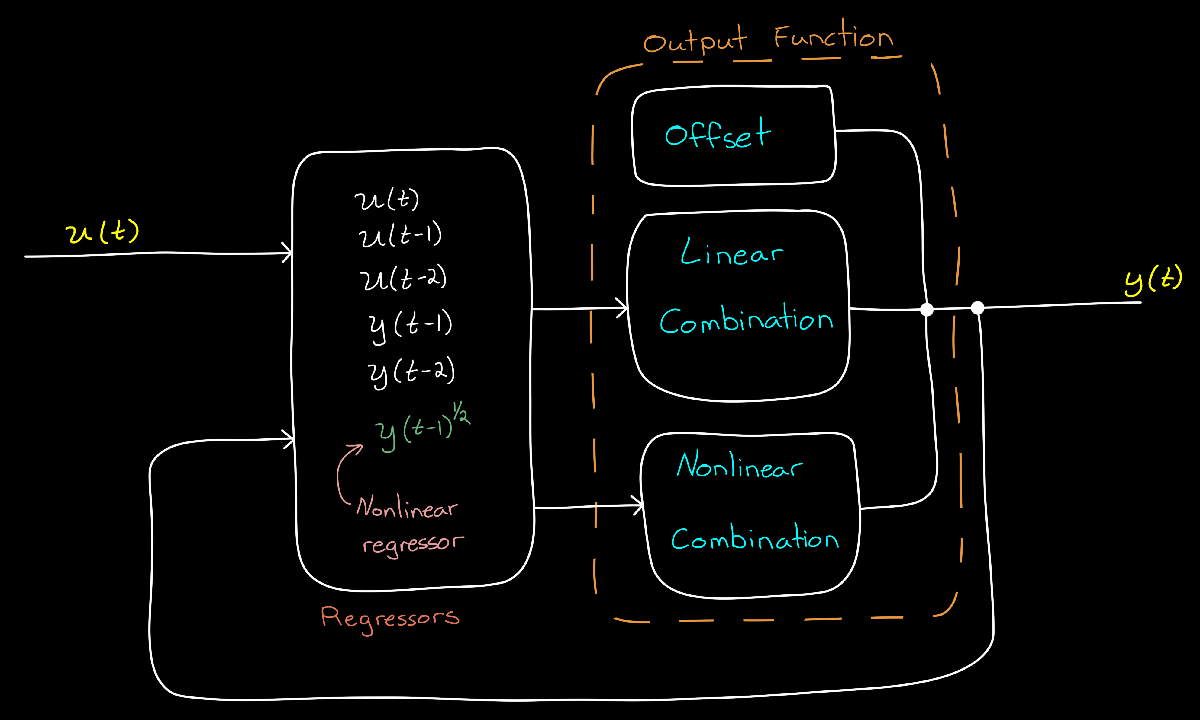

NL4_structure = idnlarx(data_est.OutputName, data_est.InputName, R, idSigmoidNetwork);

% Replace Linear model
NL4_structure.OutputFcn.LinearFcn.InputProjection = NL3.OutputFcn.LinearFcn.InputProjection;
NL4_structure.OutputFcn.LinearFcn.Value = NL3.OutputFcn.LinearFcn.Value;
NL4_structure.OutputFcn.LinearFcn.Free(:) = false;

## Fit the model to the data

opt = nlarxOptions('SearchMethod','lsqnonlin');
opt.SearchOptions.MaxIterations = 100;
NL4 = nlarx(data_est, NL4_structure, opt);
NL4.OutputFcn

ans = Sigmoid Network
Inputs: y1(t-1), y1(t-2), u1(t), u1(t-1), u1(t-2), sqrt(y1(t-1))
Output: y1(t)

 Nonlinear Function: Sigmoid network with 10 units
 Linear Function: fixed to [0.129 0.0235 -0.0399 -0.0982 0.0125 -0.0005]
 Output Offset: initialized to -0.846

          Inputs: {'y1(t-1)'  'y1(t-2)'  'u1(t)'  'u1(t-1)'  'u1(t-2)'  'sqrt(y1(t-1))'}
         Outputs: {'y1(t)'}
    NonlinearFcn: '

## Model Validation

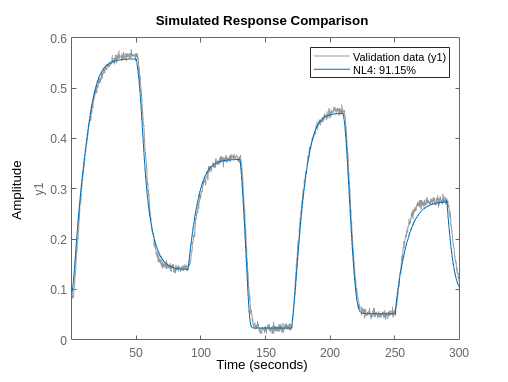

compare(data_est, NL4)

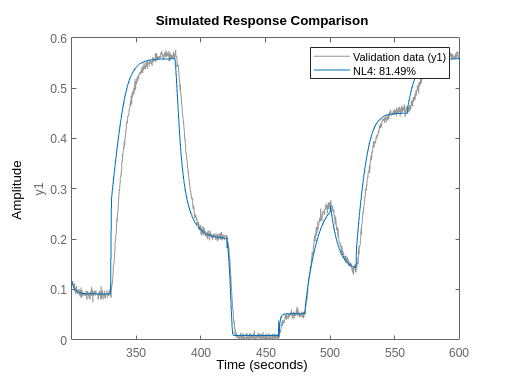

compare(data_val, NL4)